# ROZWIĄZAYWANIE UKŁADÓW RÓWNAŃ LINIOWYCH

## Współczynnik uwarunkowania

**ĆWICZENIE 1**

Na początku powtórzymy eksperyment z początku rozdziału, ale tym razem będziemy oprócz błędów rysować również wartość współczynnika uwarunkowania *cond(****A****), *aby zilustrować korelację między wartością tego współczynnika a błędem. Zwróć uwagę, że wartość *cond(****A****)* dla bardzo dobrych układów jest bliska 1.

- Zwróć uwagę, że korelacja ta nie zależy od zastosowanej metody.

- Zwróć uwagę, ze jeżeli układy równań generowane są wg jakiejś reguły - mają konkretną specyficzną budowę to często mamy do czynienia z takim zjawiskiem, że współczynnik uwarunkowania rośnie (choćby powoli) wraz rozmiarem problemu. Wiele bardziej zaawansowanych metod generuje tego typu układy równań wg pewnego szablonu.

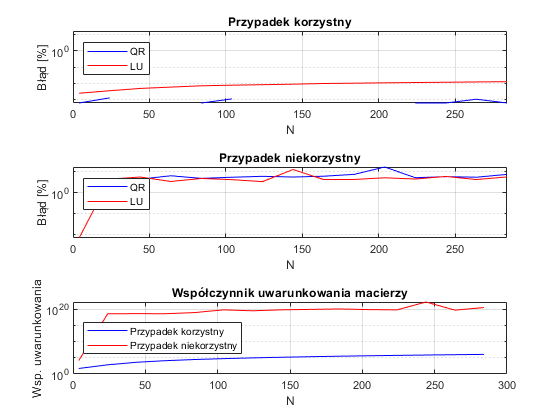

%Czyszczenie
clear all;
close all;
clc;

% Poniżej prowadzamy maksymalna ilość równań i krok z jakim ma być
% zwiększana ilość równań zaczynając od 4

Nmax=300;
step=20;

bladQR_1=[];bladLU_1=[];bladQR_2=[];bladLU_2=[];
N=[];maxNumCompThreads(1);
condA_1=[];condA_2=[];

%Generujemy losowy układ równań o rozwiązaniu bedącym wektorem samych
%jedynek
h = waitbar(0,'Rozwiazywanie...');
for i=[4:step:Nmax]
A1=magic(i)+10*eye(i);        % pierwsza maceirz - korzystna
A2=hilb(i);                   % druga macierz - niekorzystna

%Generowanie wektora b dla rozwiązania będącego wektorem samych jedynek
b1=sum(A1,2);
b2=sum(A2,2);

condA_1=[condA_1 cond(A1)];condA_2=[condA_2 cond(A2)];

%Rozwiązanie pierwszego układu równań
[timeAll, timeSimple, error]=solveUsingQRFactorization(A1,b1);
bladQR_1=[bladQR_1 error];N=[N i];warning('off');
[timeAll, timeSimple, error]=solveUsingLUFactorization(A1,b1);
bladLU_1=[bladLU_1 error];

%Rozwiązanie drugiego układu równań
[timeAll, timeSimple, error]=solveUsingQRFactorization(A2,b2);
bladQR_2=[bladQR_2 error];
[timeAll, timeSimple, error]=solveUsingLUFactorization(A2,b2);
bladLU_2=[bladLU_2 error];

%Rysowanie - skala logarytmiczna
figure(1)
tiledlayout(3,1)
nexttile
semilogy(N,bladQR_1*100+1e-16,'b',N,bladLU_1*100+1e-16,'r');xlabel("N");ylabel("Błąd [%]");grid on; 
legend("QR", "LU",'Location','northwest');axis([0 max(N) 0 (100*max([bladQR_1 bladQR_2 bladLU_1 bladLU_2])+1e-16) ]); title("Przypadek korzystny");
nexttile
semilogy(N,bladQR_2*100+1e-16,'b',N,bladLU_2*100+1e-16,'r');xlabel("N");ylabel("Błąd [%]");grid on; 
legend("QR", "LU",'Location','northwest');axis([0 max(N) 0 (100*max([bladQR_1 bladQR_2 bladLU_1 bladLU_2])+1e-16) ]);
title("Przypadek niekorzystny");
nexttile
semilogy(N,condA_1,'b',N,condA_2,'r');xlabel("N");ylabel("Wsp. uwarunkowania");grid on; 
legend("Przypadek korzystny", "Przypadek niekorzystny",'Location','west');
title("Współczynnik uwarunkowania macierzy");

waitbar(i / Nmax);
end


close(h);warning('on');

 

**ĆWICZENIE 2**

W tym ćwiczeniu będziemy generować losowe macierze układów równań o znanym rozwiązaniu składającym się z samych jedynek. Następnie będziemy zaburzać wektor b i macierz A układu równań na poziomie o kilka rzędów wielkości większym niż dokładność reprezentacji liczb w MATLAB. Dzięki temu do oszacowania błędu wg podanego na zajęciach wzoru będziemy mogli pominąć wpływ błędów zaokrągleń i reprezentacji. 

Rzeczywisty błąd względny i jego oszacowanie wykreślimy na wykresie. Dla przyspieszenia obliczeń skupimy się na metodzie LU.

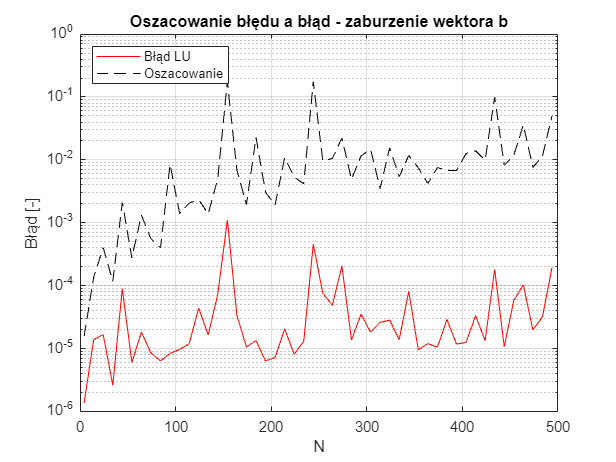

%Czyszczenie
clear all;
close all;
clc;

% Poniżej prowadzamy maksymalna ilość równań i krok z jamik ma być
% zwiększana ilość równań zaczynając od 4

Nmax=500;
step=10;

bladOszac_1=[];bladLU_1=[];
N=[];maxNumCompThreads(4);
condA_1=[];

%Generujemy losowy układ równań o rozwiązaniu bedącym wektorem samych
%jedynek
h = waitbar(0,'Rozwiazywanie...');
for i=[4:step:Nmax]
A1=rand(i);        % pierwsza maceirz - korzystna

%Generowanie wektora b dla rozwiązania będącego wektorem samych jedynek
b1=sum(A1,2);
b1org=b1;
%zaburzenie błędu na poziomie +/- 1e-6
b1 = b1.*(1 +2.*(rand(i,1)-0.5).*1e-6);

condA_1=[condA_1 cond(A1)];

%Obliczenie oszacowania
error = (norm(b1-b1org)/norm(b1org));
bladOszac_1=[bladOszac_1 cond(A1)*error];

%Rozwiązanie układu równań
N=[N i];warning('off');
[timeAll, timeSimple, error1]=solveUsingLUFactorization(A1,b1);
bladLU_1=[bladLU_1 error1];

%Rysowanie - skala logarytmiczna
figure(1)
semilogy(N,bladLU_1+1e-16,'r',N,bladOszac_1,'k--');xlabel("N");ylabel("Błąd [-]");grid on; 
legend("Błąd LU","Oszacowanie",'Location','northwest'); title("Oszacowanie błędu a błąd - zaburzenie wektora b");


waitbar(i / Nmax);
end


close(h);warning('on');

 

Poniższy kod przeprowadza ten sam eksperyment dla zaburzenia macierzy A. 

- Zwróć uwagę, że z postaci wzoru wynika, że istnieje ograniczenie na wskazywany błąd wynoszące 100%

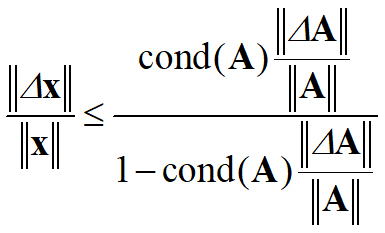

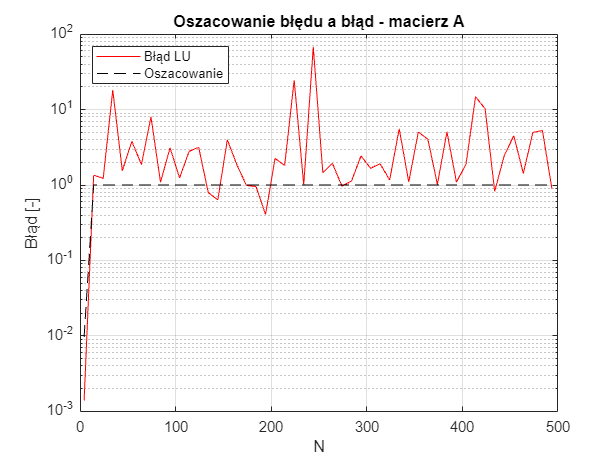

%Czyszczenie
clear all;
close all;
clc;

% Poniżej prowadzamy maksymalna ilość równań i krok z jamik ma być
% zwiększana ilość równań zaczynając od 4

Nmax=500;
step=10;

bladOszac_1=[];bladLU_1=[];
N=[];maxNumCompThreads(4);
condA_1=[];

%Generujemy losowy układ równań o rozwiązaniu bedącym wektorem samych
%jedynek
h = waitbar(0,'Rozwiazywanie...');
for i=[4:step:Nmax]
A1=hilb(i);        % pierwsza maceirz - korzystna

%Generowanie wektora b dla rozwiązania będącego wektorem samych jedynek
b1=sum(A1,2);
A1org=A1;
%zaburzenie błędu na poziomie +/- 1e-6
A1 = A1.*(1 +2.*(rand(i)-0.5).*1e-6);

condA_1=[condA_1 cond(A1org)];

%Obliczenie oszacowania
error = (norm(A1-A1org)/norm(A1org));
bladOszac_1=[bladOszac_1 abs(cond(A1org)*error/(1-cond(A1org)*error))];

%Rozwiazanie układu równań
N=[N i];warning('off');
[timeAll, timeSimple, error1]=solveUsingLUFactorization(A1,b1);
bladLU_1=[bladLU_1 error1];

%Rysowanie - skala logarytmiczna
figure(1)
semilogy(N,bladLU_1+1e-16,'r',N,bladOszac_1,'k--');xlabel("N");ylabel("Błąd [-]");grid on; 
legend("Błąd LU","Oszacowanie",'Location','northwest'); title("Oszacowanie błędu a błąd - macierz A");


waitbar(i / Nmax);
end


close(h);warning('on');

 

**ĆWICZENIE 3**

Jak do tej pory wszystkie nasze testy wskazują, że rozkład QR ma gorsze parametry niż LU. I faktycznie przy współczesnych metodach i algorytmach obliczania rozkładu LU daje on znacznie lepsze wyniki dla macierzy kwadratowych. 

Tymczasem rozkład QR jest jednym z niewielu rozkładów który pozwala zanalizować macierze prostokątne opisujące układy równań nad określonych. Problem rozwiązania tego typu układów równań liniowych poruszymy później. 

Wprowadzenie współczynnika uwarunkowania pozwala, wraz z innymi właściwościami macierzy A, na automatyczny dobór właściwej metody tak, aby uzyskać najlepsze i najszybsze rozwiązanie. Poniżej pokazano typowe drzewo decyzyjne MATLABa uruchamiane przy wykorzystaniu operatora wbudowanego "\"

- Zwróć uwagę gdzie znajdują się metody poznane - rozkład QR i rozkład LU

Meto rozwiązania tego problemu jest znacznie więcej niż poznaliśmy na wykładzie - MATLAB implementuje również metody bardziej zaawansowane

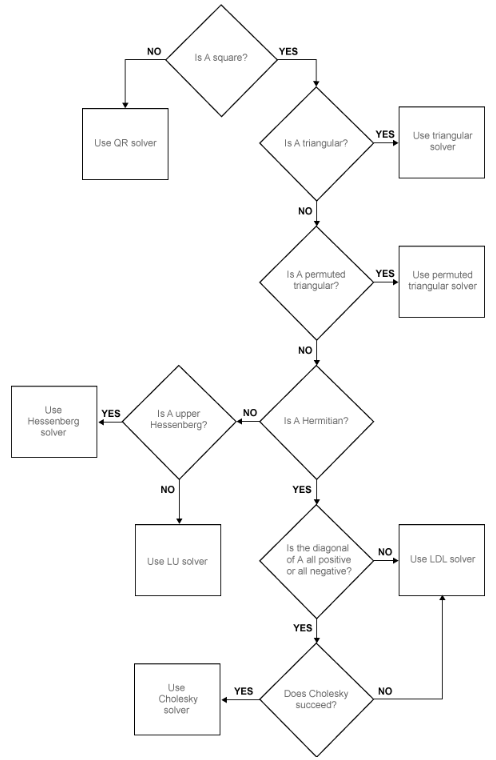

## Wykorzystywane funkcje

function [timeAll, timeSimple, error]=solveUsingQRFactorization(A,b)

%Startujemy licznik czasu
time1 = tic;

%Rozkład QR
[Q,R]=qr(A);

%Startujemy licznik tylko obliczenia
time2 = tic;

%Rozwiązanie metodą QR w dwóch krokach zapisane w jednej linijce żeby
%prawidłowo mierzyć złożoność
y=Q'*b; 
x=R\y;

%Zakończenie liczenia czasu
time2end = toc(time2);
time1end = toc(time1);

%Obliczenie błędów zakładając, ze rozwiazaniem jest wektor jedynek
error=(norm(x - ones(numel(b),1)))/norm(ones(numel(b),1));

%Inne wartosci wyjściowe
timeAll=time1end;
timeSimple=time2end;
end

function [timeAll, timeSimple, error]=solveUsingLUFactorization(A,b)

%Startujemy licznik czasu
time1 = tic;

%Rozkład LU
%[L,U,P]=lu(A);
[L,U]=lu(A);

%Startujemy licznik tylko obliczenia
time2 = tic;

%Rozwiązanie metodą LU w dwóch krokach zapisane w jednej linijce żeby
%prawidłowo mierzyć złożoność
x = U\(L\b);
% Rozpisane na dwie linijki byłoby y = L\(P*b); x = U\y;

%Zakończenie liczenia czasu
time2end = toc(time2);
time1end = toc(time1);

%Obliczenie błędów zakłądając, ze rozwiązaniem jest wektor jedynek
error=(norm(x-ones(numel(b),1)))/norm(ones(numel(b),1));

%Inne wartosci wyjściowe
timeAll=time1end;
timeSimple=time2end;
end

